clear; clc;

## E1

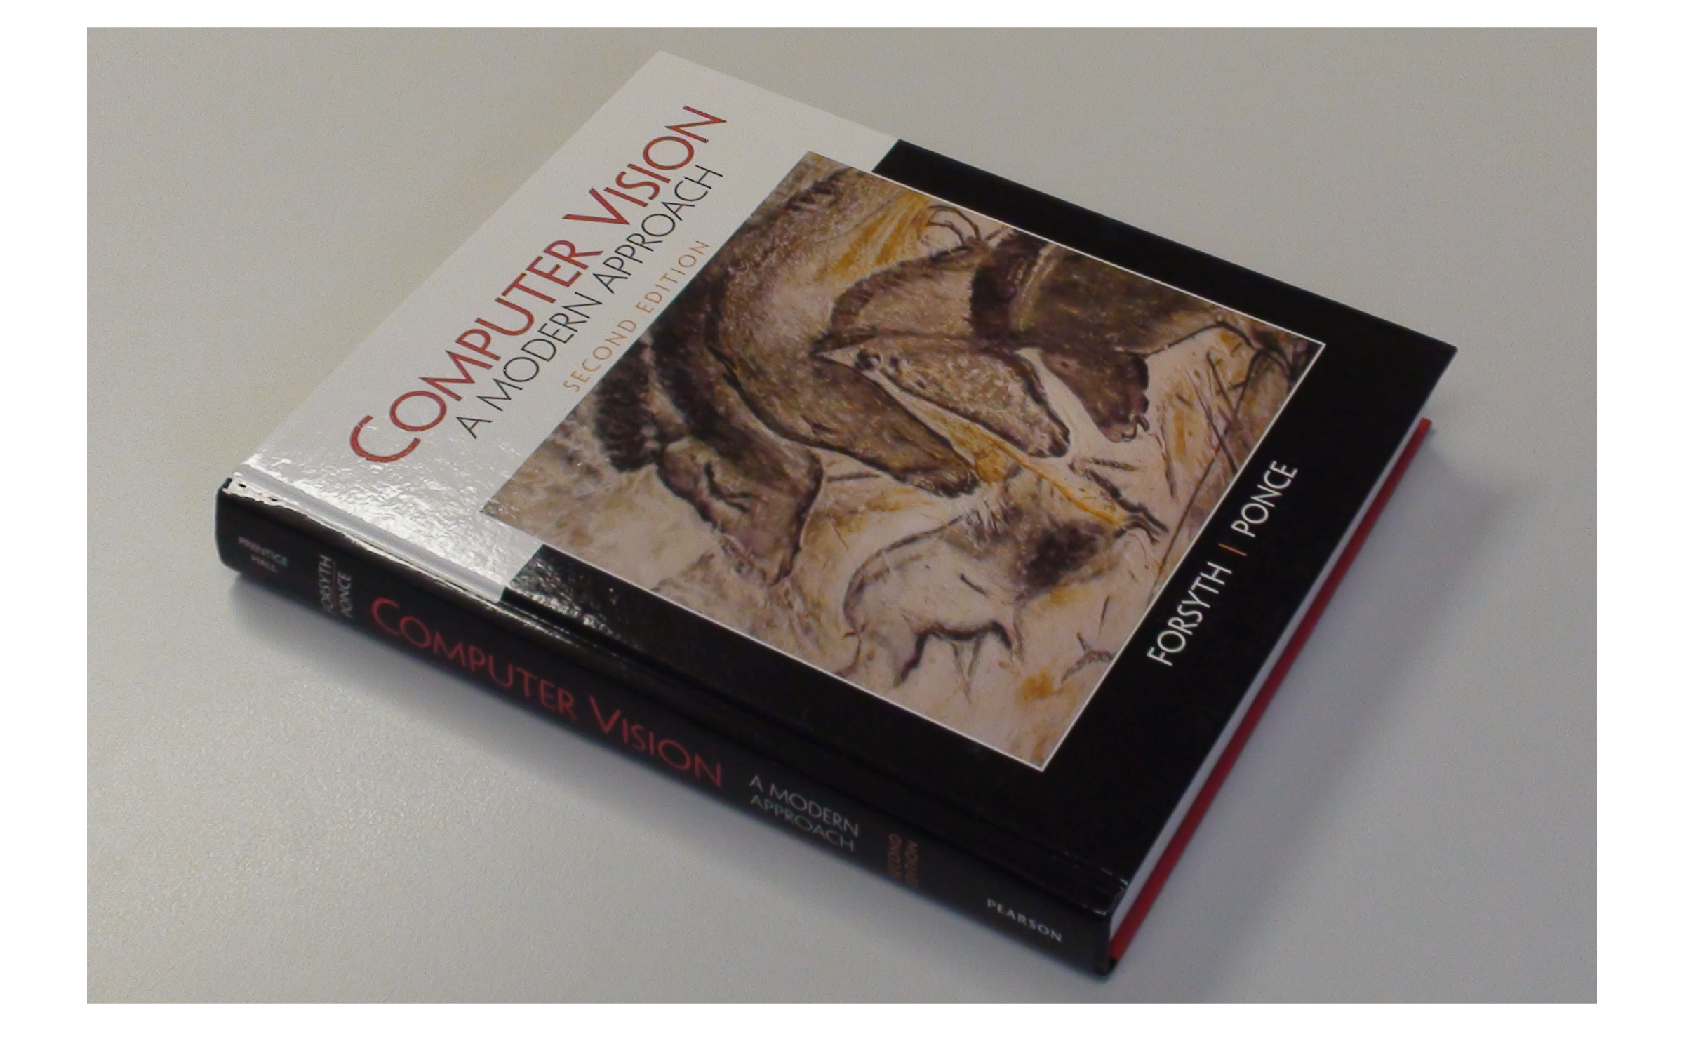

book = imread("Book.bmp");
% imshow(book)

% impixelinfo
% 4 corners info
% (559, 693)  [198 194 191]
% (1359, 1064)  [31 18 25]
% (1030, 184)  [145 127 107]
% (1762, 454)  [162 156 160]

% Four points in input image: 
% each row is one point x (horizontal)- y (vertical)
input_points = [559, 693; 
 1359, 1064;
 1030, 184;
 1762, 454]

input_points =          559         693
        1359        1064
        1030         184
        1762         454



% Corresponding four points in output image 
% each row is one point w (horizontal)- z (vertical)
output_points = [500, 500;
 500, 1000;
 1000, 500;
 1000, 1000] 

output_points =          500         500
         500        1000
        1000         500
        1000        1000


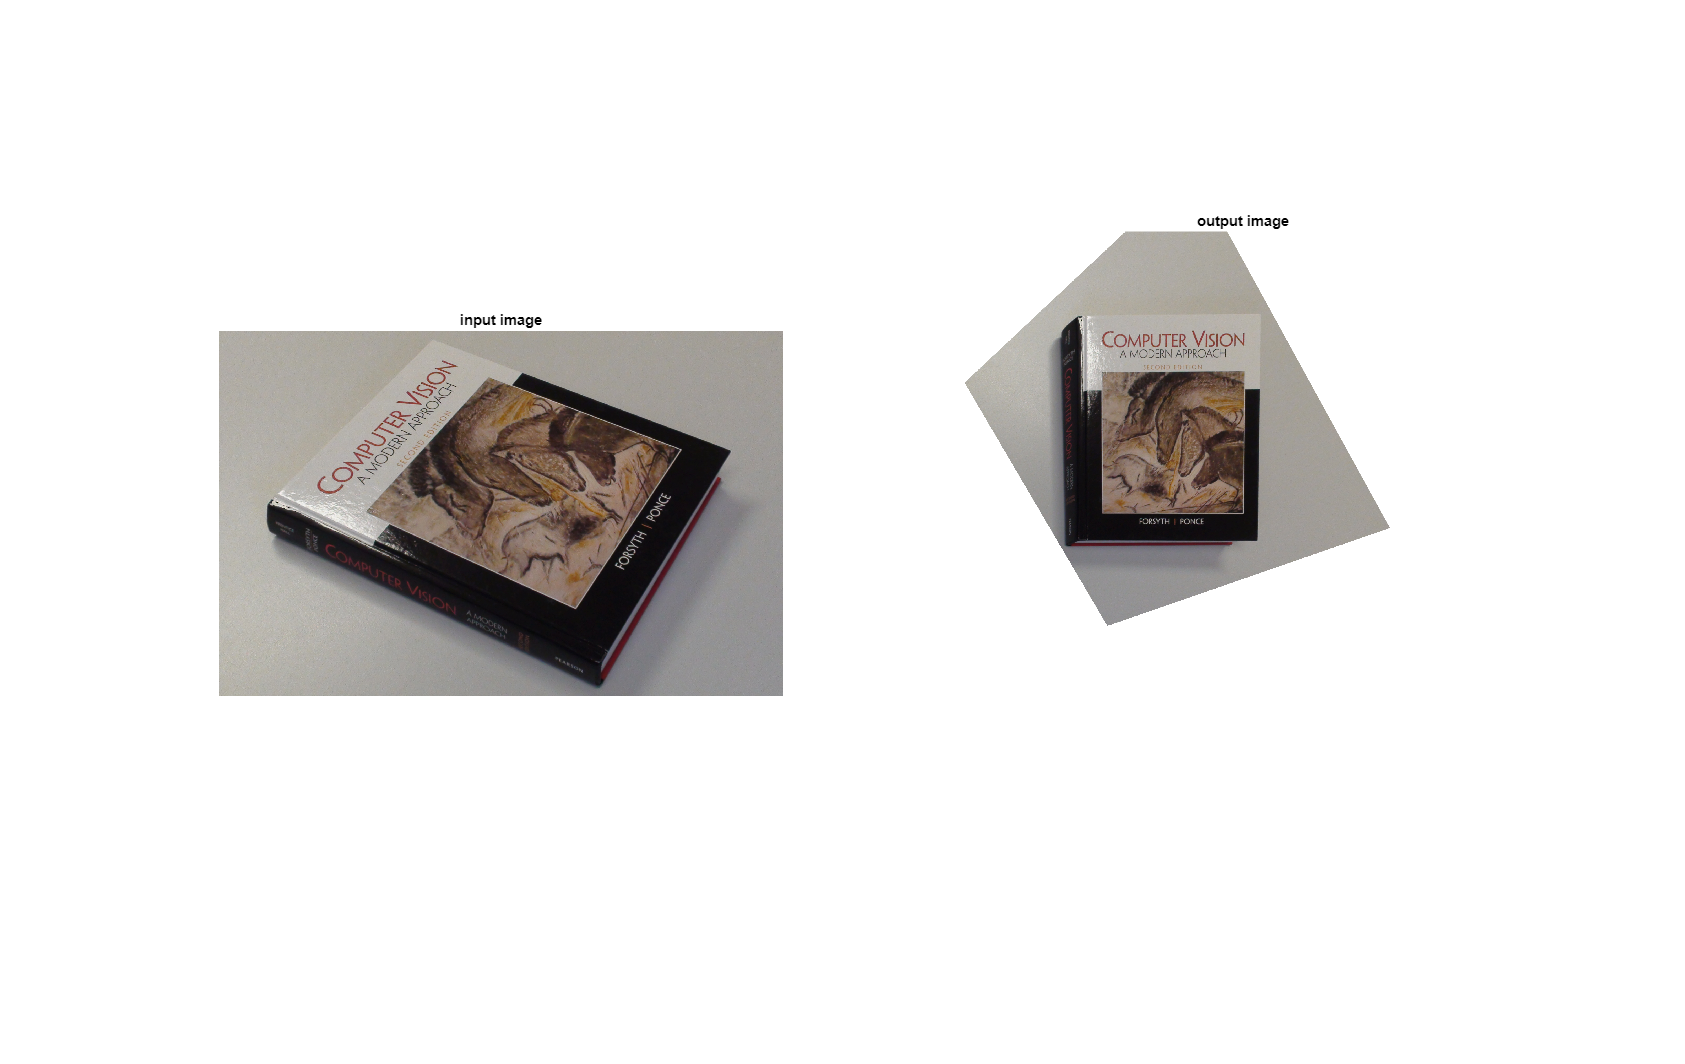


% Obtain a description of projective transformation [important] 
tform = cp2tform(input_points, output_points, 'projective');
% Apply the projective transformation
g = imtransform(book, tform, 'XData',[1 2000], 'YData',[1 2000], 'FillValue',255);

% Display images
subplot(1,2,1), imshow(book), title('input image');
subplot(1,2,2), imshow(g), title('output image');

## E2

clear; clc;

fpga = imread("FPGA.bmp");
imshow(fpga)
% impixelinfo
% 4 corners info
% (84, 235)  [182 184 171]
% (118, 517)  [199 202 200]
% (535, 131)  [202 209 185]
% (742, 511)  [209 208 204]

% Four points in input image: 
% each row is one point x (horizontal)- y (vertical)
input_points = [84, 235; 
 118, 517;
 535, 131;
 742, 511]

input_points =     84   235
   118   517
   535   131
   742   511



% Corresponding four points in output image 
% each row is one point w (horizontal)- z (vertical)
output_points = [500, 500;
 450, 1000;
 1000, 500;
 1000, 1000] 

output_points =          500         500
         450        1000
        1000         500
        1000        1000


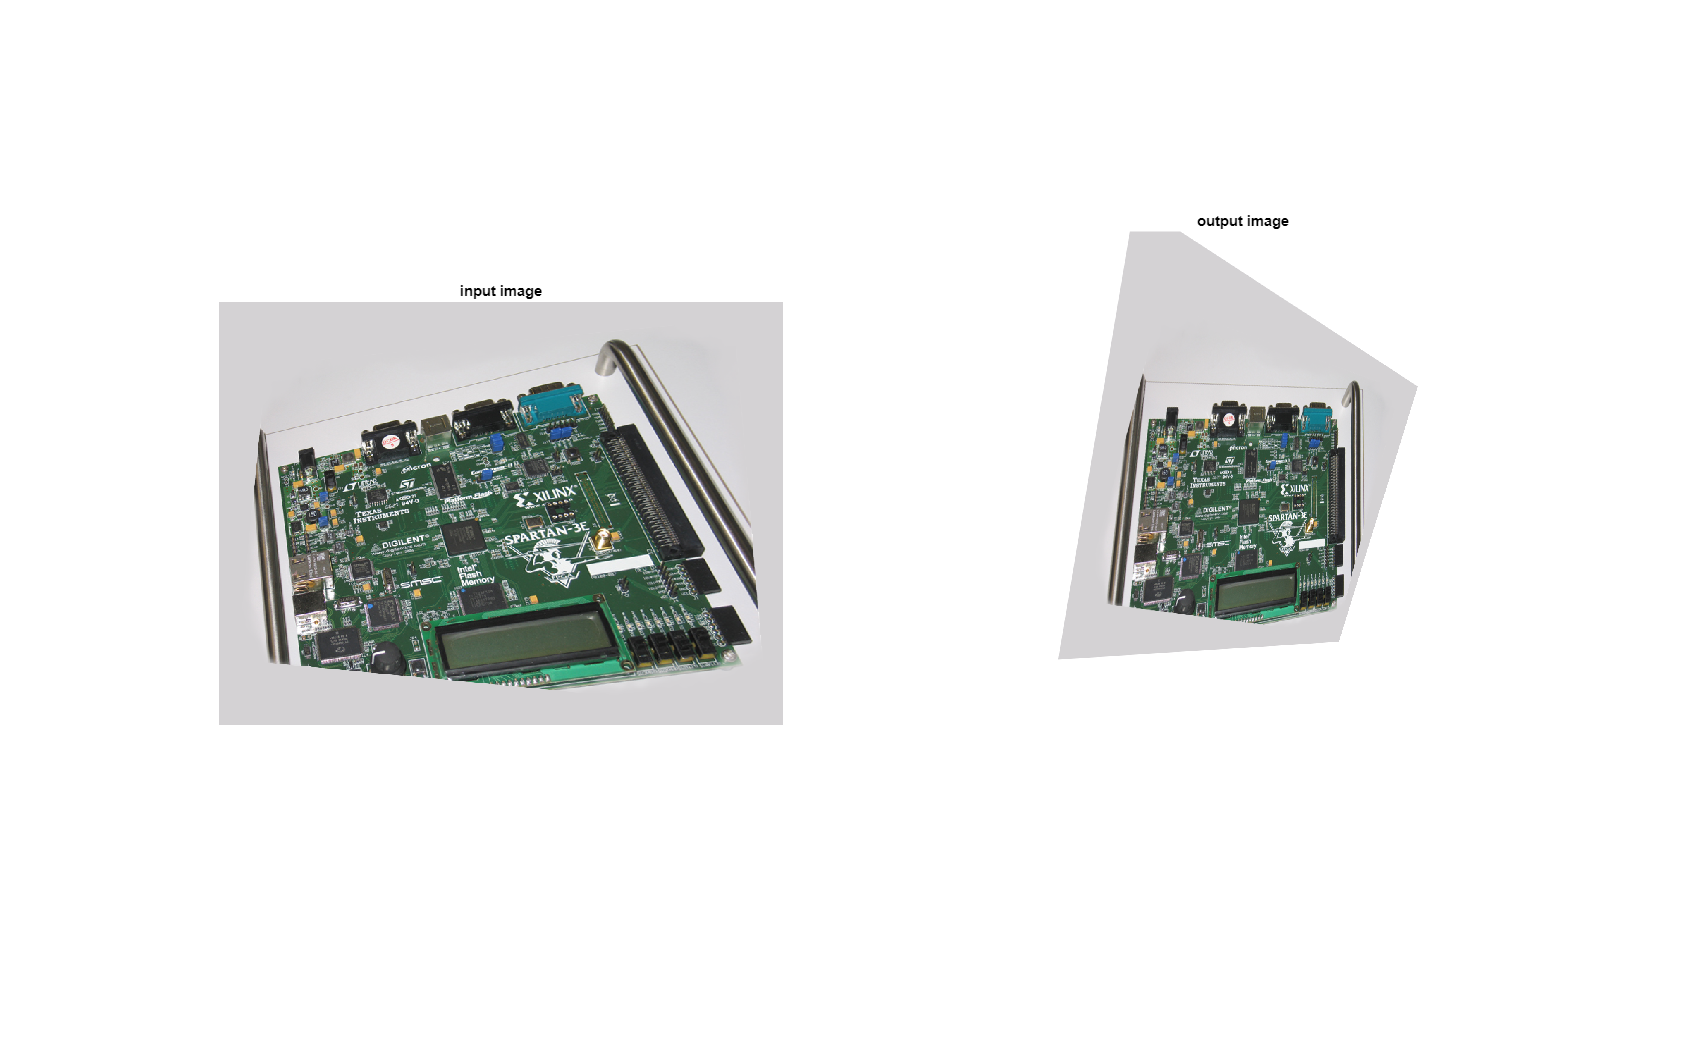


% Obtain a description of projective transformation [important] 
tform = cp2tform(input_points, output_points, 'projective');
% Apply the projective transformation
g = imtransform(fpga, tform, 'XData',[1 1500], 'YData',[1 1500], 'FillValue',255);

% Display images
subplot(1,2,1), imshow(fpga), title('input image');
subplot(1,2,2), imshow(g), title('output image');